# 第七章计算物理作业：3，4，5，7，9；

## 3.解方程：

## 
$$\left\{
\begin{array}{l}
u_{xx}+u_{yy}=xe^y,\quad(0<x<2,0<y<1)\\
u(0,y)=0,\quad u(2,y)=2e^y\\
u(x,0)=x,\quad u(x,1)=ex
\end{array}$$


## 取$\Delta x=1/3,\Delta y=1/5$.

%松弛法解泊松方程
clear;clc;
omega=1.5;  %w<2低松弛
dx=1/3;dy=1/5;  %设置Δx Δy
x=0:dx:2;
y=0:dy:1;
Nx=length(x);
Ny=length(y);
%定解条件
phi(:,Nx)=2*exp(1).^y';
phi(1,:)=x;
phi(Ny,:)=exp(1).*x;
%根据松弛法公式迭代求解
for N=1:100
    for i=2:Ny-1
        for j=2:Nx-1
            ph=(phi(i+1,j)+phi(i-1,j)+phi(i,j+1)+phi(i,j-1));
            phi(i,j)=(1-omega)*phi(i,j)+0.25*omega*(ph-dx*dy*x(i)*exp(1)^y(i));
        end
    end
end
%作图
surf(x,y,phi,'EdgeColor','none')

## 4.解方程：

## 
$$\left\{\begin{array}{ll}
u_t=u_{xx}\quad(0<x<1,0<t<0.5)\\
u(x,0)=sin\pi x\\
x(0,t)=u(1,t)=0
\end{array}$$


## 分别取$\Delta x=0.1,\Delta t=0.01\;\text{和}\;\Delta x=0.1,\Delta t=0.001$进行计算。并与解析解$u(x,t)=exp(-\pi t)sin(\pi x)$比较。

### (1)$\Delta x=0.1,\Delta t=0.01\;$

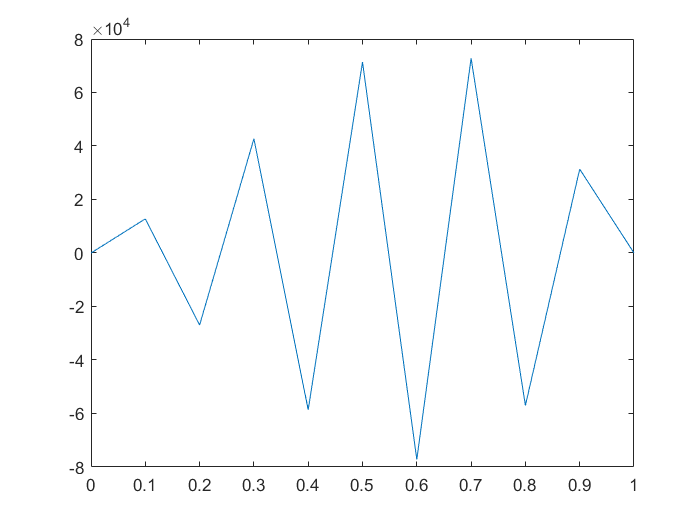

%差分法解热传导方程
%r=1，不满足0<=r<=1/2的稳定条件
%不满足稳定条件，前一刻产生的计算误差会扩大下一刻的计算误差，造成数值解失真
clear;clc;
delta_x=0.1;delta_t=0.01;
x=0:delta_x:1;
t=0:delta_t:0.5;
a2=1;
r=delta_t/delta_x^2*a2;
%设置初始条件
u=zeros(length(x),length(t));
u(2:length(x)-1,1)=sin(pi.*x(2:end-1));
u(1,:)=0;u(length(x),:)=0;
%根据差分公式进行数值计算并作图
for j=1:length(t)-1
    u(2:length(x)-1,j+1)=(1-2*r)*u(2:length(x)-1,j)+r*(u(1:length(x)-2,j)+u(3:length(x),j));
    plot(x,u(:,j));
    pause(0.05)
end

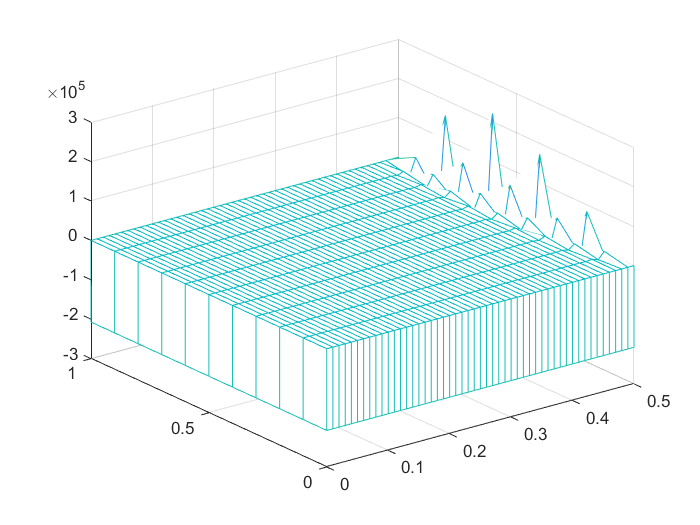

[X,T]=meshgrid(t,x);
meshz(X,T,u)

### (2)$\Delta x=0.1,\Delta t=0.001$

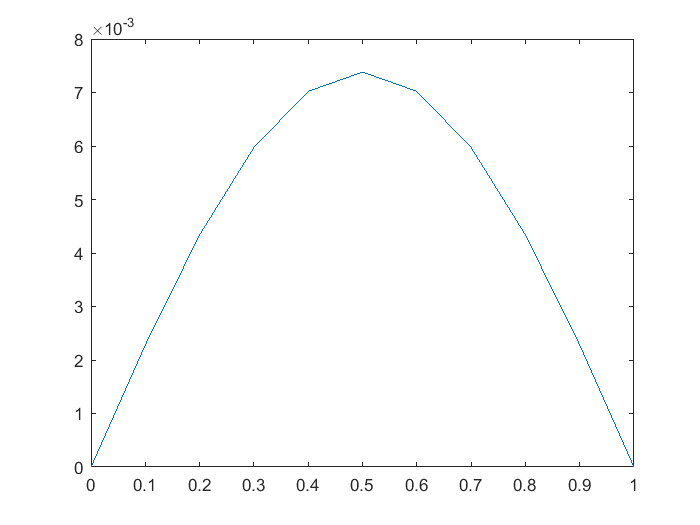

%差分法解热传导方程
%r=0.1，满足0<=r<=1/2的稳定条件
%满足稳定条件，数值解稳定，结果可靠
clear;clc;
delta_x=0.1;delta_t=0.001;
x=0:delta_x:1;
t=0:delta_t:0.5;
a2=1;
r=delta_t/delta_x^2*a2;
%设置初始条件
u=zeros(length(x),length(t));
u(2:length(x)-1,1)=sin(pi.*x(2:end-1));
u(1,:)=0;u(length(x),:)=0;
%根据差分公式进行数值计算并作图
for j=1:length(t)-1
    u(2:length(x)-1,j+1)=(1-2*r)*u(2:length(x)-1,j)+r*(u(1:length(x)-2,j)+u(3:length(x),j));
    plot(x,u(:,j));
    pause(0.01)
end

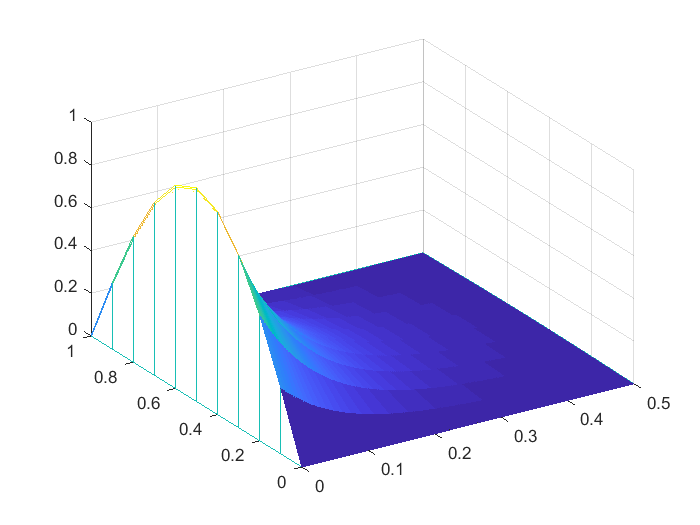

[X,T]=meshgrid(t,x);
meshz(X,T,u)

$0 \leq r \leq 1/2$为稳定条件

当不满足稳定条件时，前一刻产生的计算误差会扩大下一刻的计算误差，造成数值解失真。

## 5.用差分法和PDETOOL解方程：

## 
$$\left\{
\begin{array}{l}
u_{tt}=a^2u_{xx}\quad (0<x<l,0<t)\\
u(0,t)=0,\quad u(l,t)=Asin \omega t\\
u(x,0)=0,\quad u_t(x,0)=0
\end{array}
\right.$$


## 问题中的参数由自己选择。

### 弦长$l$取2，$w$取$\pi$.

### （1）差分法：

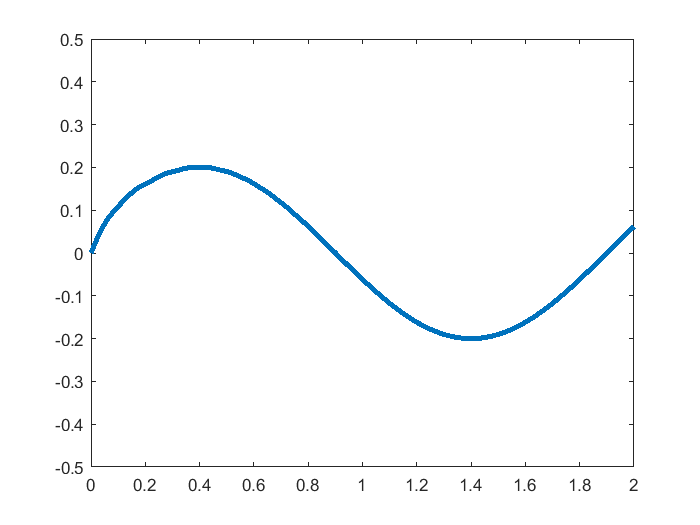

%差分法解弦振动方程
clear;clc;
dx=0.02;
dt=0.01; c=dt*dt/dx/dx;
x=0:dx:2;
x=x';
t=0:dt:2.1;
Nx=length(x);
Nt=length(t);
%设置初始条件
u=zeros(Nx,Nt);
u(1,:)=0;
u(Nx,:)=0.2*sin(pi*t);
u(1:Nx,1)=0;
u(2:Nx-1,2)=u(2:Nx-1,1)+c/2*(u(3:Nx,1)-2*u(2:Nx-1,1)+u(1:Nx-2,1));
uu=u;
%根据差分公式进行数值计算
for k=2:Nt
    uu(2:Nx-1,k)=u(2:Nx-1,2);   %uu存储每次迭代的结果
    u(Nx,2)=u(Nx,k);
    u(2:Nx-1,3)=2*u(2:Nx-1,2)-u(2:Nx-1,1)+c*(u(3:Nx,2)-2*u(2:Nx-1,2)+u(1:Nx-2,2));
    u(2:Nx-1,1)=u(2:Nx-1,2);
    u(2:Nx-1,2)=u(2:Nx-1,3);
end
%动画作图
for j=1:Nt
    plot(x, uu(:,j),'linewidth', 3);
    axis([0,2,-0.5,0.5]);
    drawnow()
end

### （2）用PDETOOL求解：

1.设置矩形区域：$-0.1 \leq x \le 0.1;\quad 0 \leq y\leq 2;$

2.设置边界条件：上下边界条件都为Neumann类型，$g=0;q=0.$

3.设置PDE公式为Hyperbolic型，$c=1;d=1;a=0;f=0;$

4.讲初始化的网格做两次细分。

5.在解方程的参数对话框中设置解方程参数$t=0:0.01:2.1$，其余不变。

6.在作图选项对话框中，选择Color，Height(3-D plot)，Animation。

7.最后plot得到结果如下图：

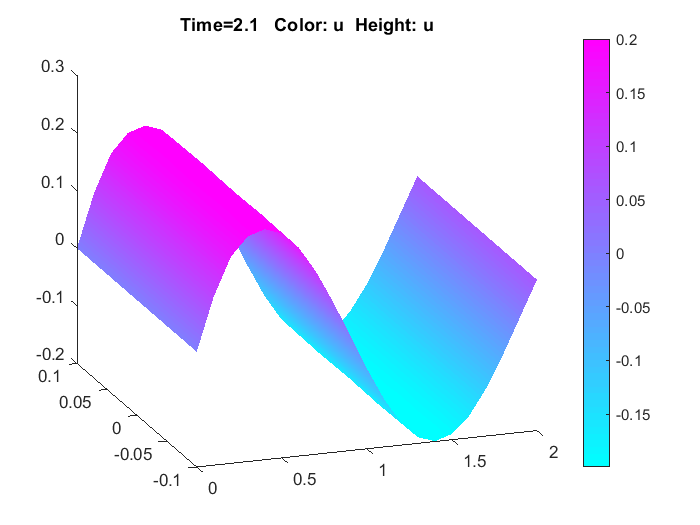

## 7.用偏微分方程工具箱求解如下的定解问题：

## 
$$\left\{
\begin{array}{l}
u_t=a^2u_{xx}\\
u(0,t)=0,\quad u_x(l,t)=0\\
u(x,0)=u_0x/l
\end{array}
\right.$$


### 题中$l $取2.

1.设置矩形区域：$-0.1 \leq x \le 0.1;\quad 0 \leq y\leq 2;$

2.设置边界条件：上下边界条件都为Neumann类型，$g=0;q=0.$

3.设置PDE公式为Parabolic型，$c=1;d=1;a=0;f=0;$

4.讲初始化的网格做两次细分。

5.在解方程的参数对话框中设置解方程参数$t=0:0.01:5$，其余不变。

6.在作图选项对话框中，选择Color，Animation。

7.最后plot得到结果如下图：

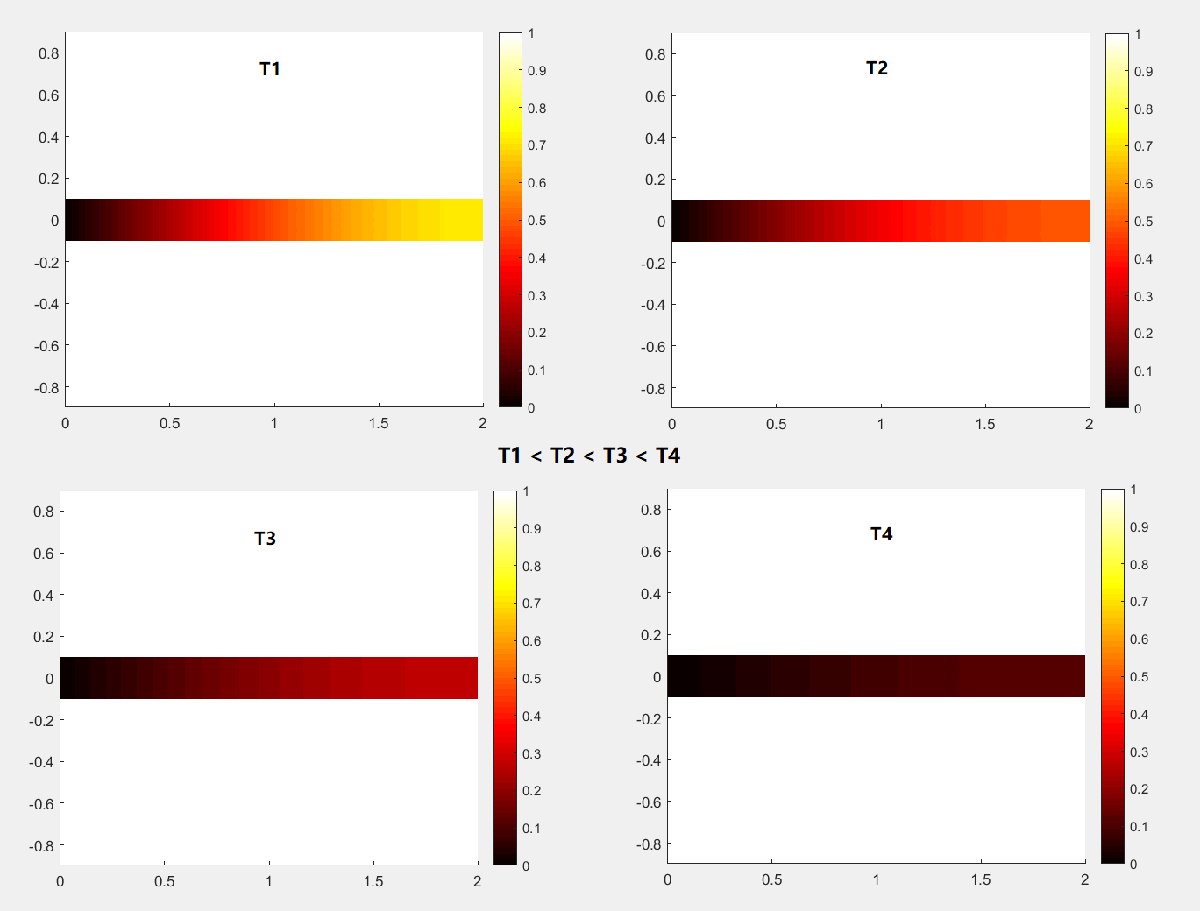

随着时间变化，温度逐渐趋于平衡

## 9.根据量子力学，一维线性谐振子的波函数是：

## 
$$\psi_n=N_nH_n(\xi)e^{-\frac{1}{2}\xi^2},\quad n=0,1,2,···$$


## 其中$N_n$为归一化常数，$H_n(\xi)$是厄密多项式。画出谐振子的前四个波函数，并于之前数值法图形比较。

syms x y
for j=0:3
    subplot(2,4,j+1)
    fplot(hermiteH(j,x)*exp(1)^(-0.5*x^2),'linewidth',1.5)
    %grid on
    %ylabel('ψ_n(x)')
    %legend('ψ_0(x)', 'ψ_1(x)', 'ψ_2(x)', 'ψ_3(x)', 'Location', 'Best')
    %title('谐振子波函数')
end


%--第五章数值解法------------------------------------------------------
n=4;eold=-1;olddpsi=0.5; tol=1e-6;
wlch5fun=@(x,psi,e1)[psi(2);50^2*(-e1-1+x^2/2)*psi(1)];
for k=1:n
    de=2*tol;e1=eold+abs(eold)/70;
    while abs(de)>tol
        xturn=-sqrt(2*(e1+1));kk=(-1)^(k+1)*0.0001;
        [x1,u1]=ode45(@(x,psi)wlch5fun(x,psi,e1),[-1 xturn],[0 kk]);
        [x2,u2]=ode45(@(x,psi)wlch5fun(x,psi,e1),[1 xturn],[0 -0.0001]);
        dpsi=u1(length(x1),2)-u2(length(x2),2);
        de=-dpsi*de/(dpsi-olddpsi);
        olddpsi=dpsi; eold=e1; e1=e1+de;
    end
e(k)=eold;
subplot(2,4,k+4);plot(x1,u1(:,1),x2,u2(:,1),'linewidth',1);
end

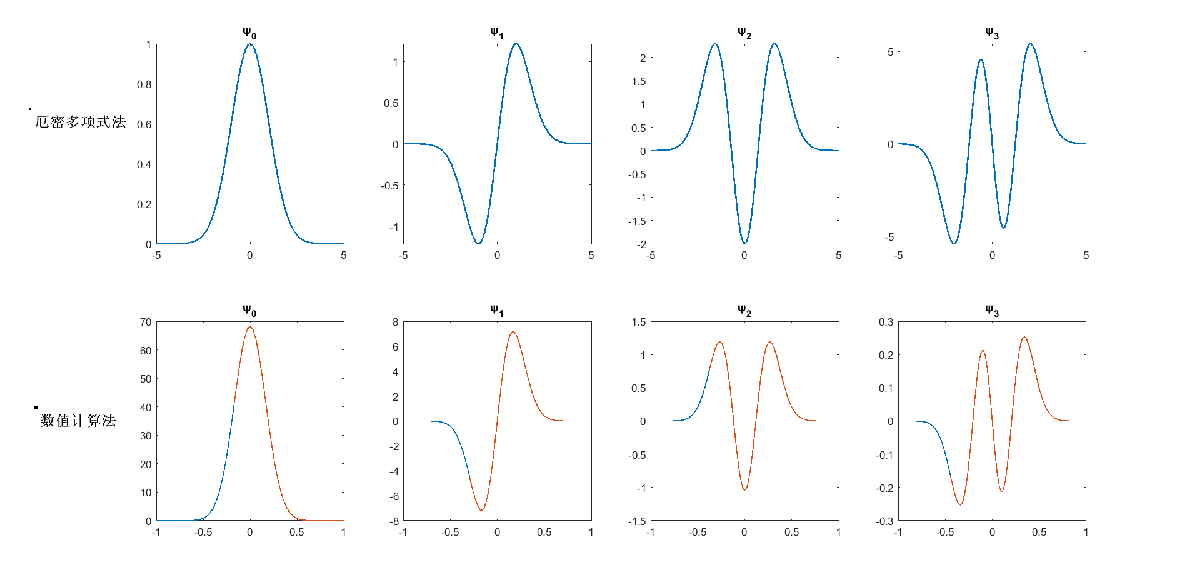

通过比较可以得出：用厄密多项式得出的波函数和数值解法得出的波函数相同